# Sessió 8

## Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna

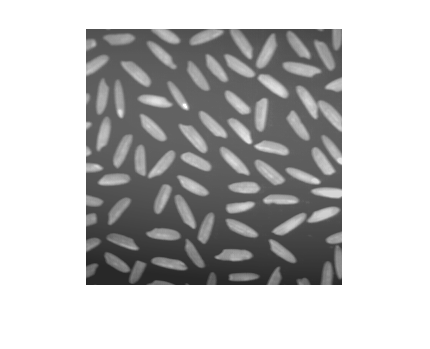

im = imread('arros.tif');
imshow(im), title('Original')

## Segmentació de la imatge (Otsu)

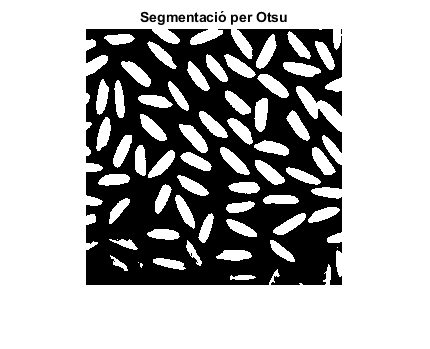

th = graythresh(im);
bw = im2bw(im, th);
figure, imshow(bw), title('Segmentació per Otsu')

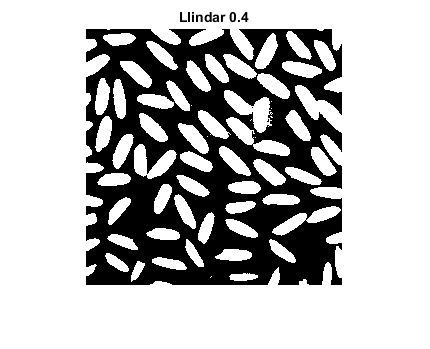

% La binarització no és bona
bw = im2bw(im, 0.4);
figure, imshow(bw), title('Llindar 0.4')

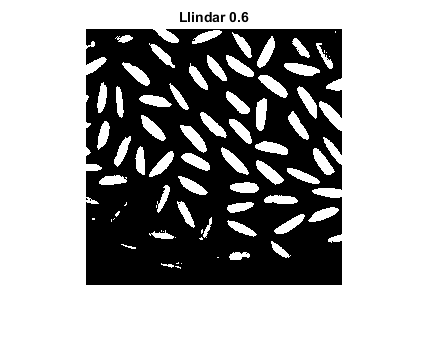

bw = im2bw(im, 0.6);
figure, imshow(bw), title('Llindar 0.6')

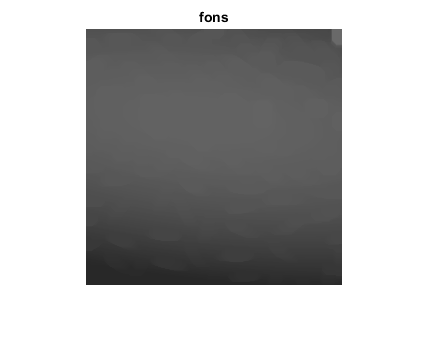


ee = strel('disk', 10);
op = imopen(im, ee);
figure, imshow(op), title('fons')

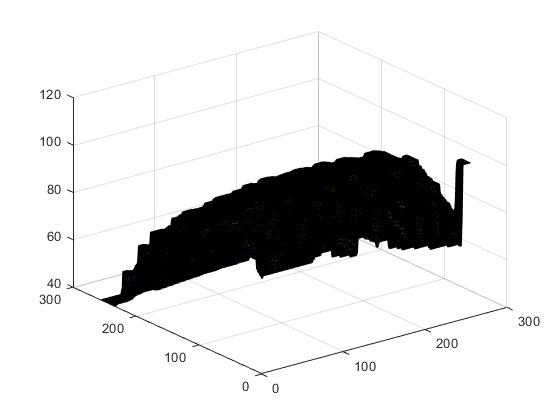

figure, surf(op)

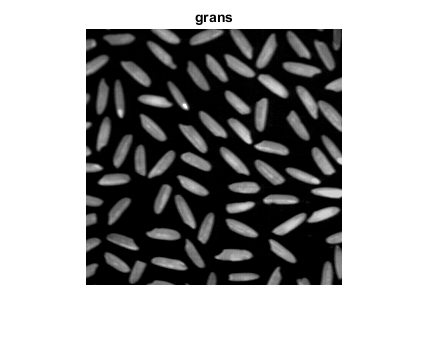

grans = imsubtract(im, op);
figure, imshow(grans, []), title('grans')

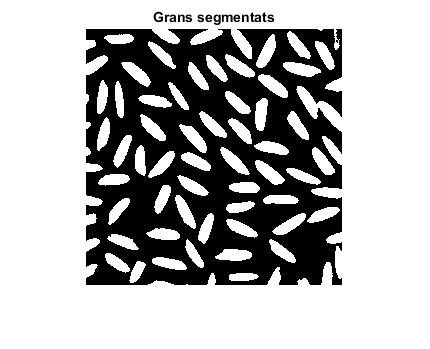

th = graythresh(grans);
bw = im2bw(grans, th);
figure, imshow(bw), title('Grans segmentats')

#### Etiquetatge

eti = bwlabel(bw, 4);
max(eti(:))

ans = 81

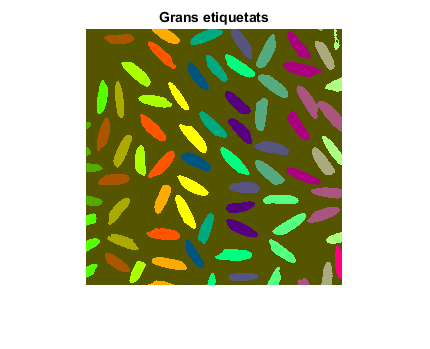

figure, imshow(uint8(eti)), title('Grans etiquetats'), colormap('colorcube')

## Extreure dades (Característiques)

dades = regionprops(eti, 'all');
arees = [dades.Area];
dades(50).Area

ans = 305

figure, plot(arees)
clear all
close all

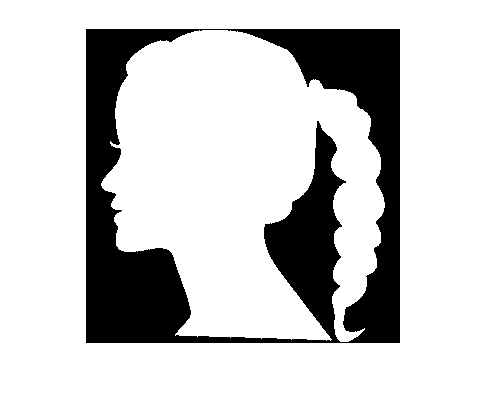

im = imread('head.png');
im = imresize(im, 1/2);
imshow(im)

area = sum(im(:))

area = 58501

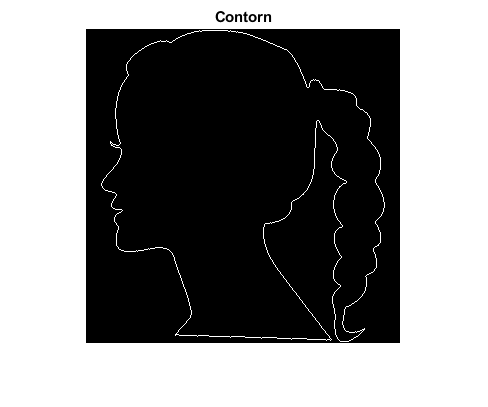

ero = imerode(im, strel('disk', 1));
cont = imsubtract(im, ero);
figure, imshow(cont), title('Contorn')

perm = sum(cont(:))

perm = 1526

C = perm * perm/area

C = 39.8057

C/(4 * pi)

ans = 3.1676

[fila col] = find(cont, 1)

fila = 155

col = 16

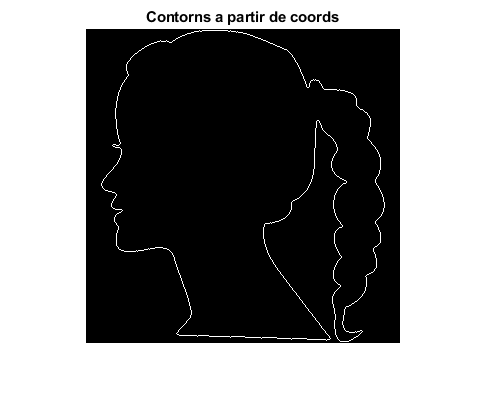

B = bwtraceboundary(cont, [fila, col], 'E');
aux = zeros(size(im));
aux(sub2ind(size(aux), B(:, 1), B(:, 2))) = 1;
figure, imshow(aux), title('Contorns a partir de coords')

## Exercici: Codi de Freeman

[fila cols] = size(B);
V = B(2:fila, :)-B(1:(fila - 1), :);
V

V =      1     0
     1     0
     1     1
     1     0
     1     1
     1     1
     1     1
     0     1
     0     1
     1     1


sol = zeros(size(V, 1), 1);
sol = mod((atan2d(V(:, 2), V(:, 1)) + 360)/45, 8) + 1;
sol

sol =      1
     1
     2
     1
     2
     2
     2
     3
     3
     2



%%%%%%%%  DIRECCIONS   %%%%%%%
%           7
%       6       8
%            
%   5              1
%            
%       4       2
%           3
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Fourier 

cdm = mean(B)

cdm =   176.7956  180.6357


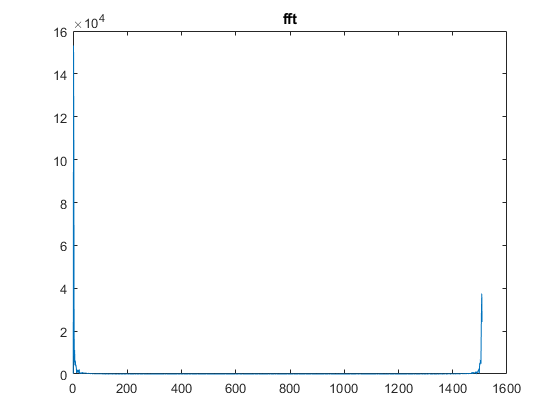

Bc(:, 1) = B(:, 1) - cdm(1);
Bc(:, 2) = B(:, 2) - cdm(2);
s = Bc(:, 1) + i * Bc(:, 2);
s(end+1) = s(end);
z = fft(s);
figure, plot(abs(z)), title('fft')

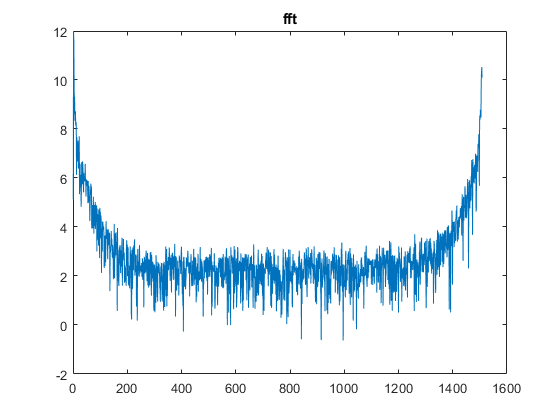

figure, plot(log(abs(z))), title('fft')

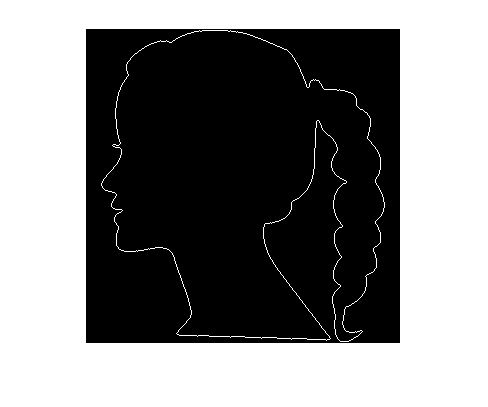

s2 = ifft(z);
files = round(real(s2) + cdm(1));
cols = round(imag(s2) + cdm(2));
aux = zeros(size(im));
aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux)

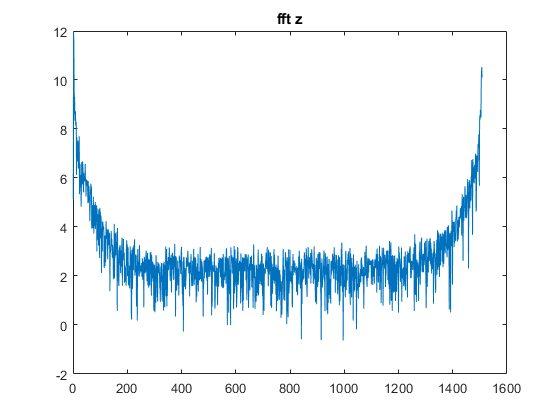

N = 30;
tmp = z;
tmp(N+1:end-N) = 0;
figure, plot(log(abs(z))), title('fft z')

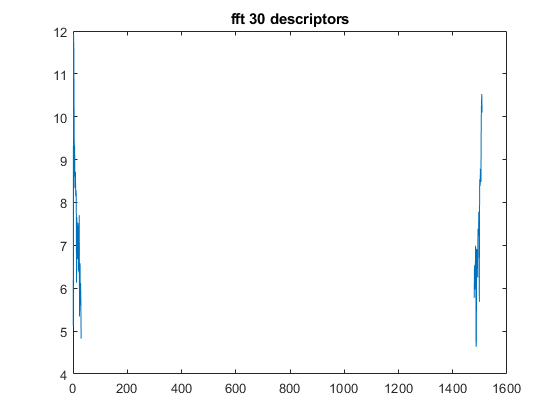

figure, plot(log(abs(tmp))), title('fft 30 descriptors')

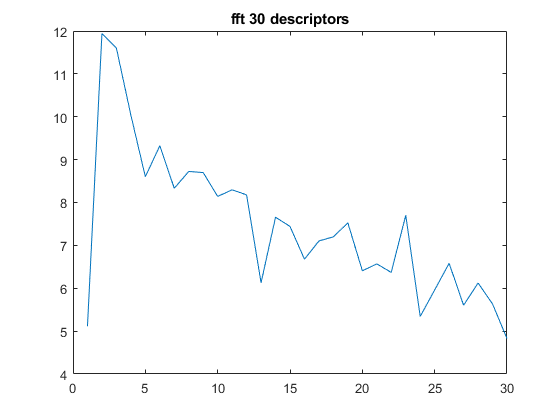

figure, plot(log(abs(tmp(1:30)))), title('fft 30 descriptors')

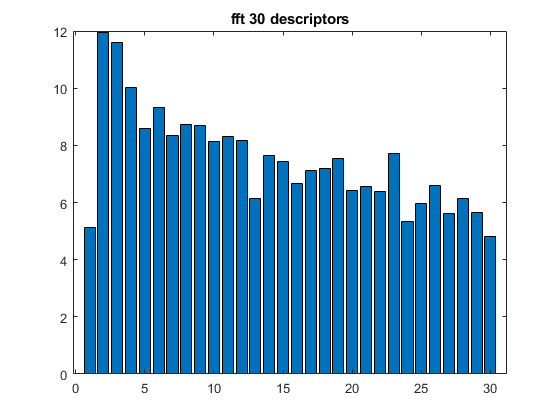

figure, bar(log(abs(tmp(1:30)))), title('fft 30 descriptors')

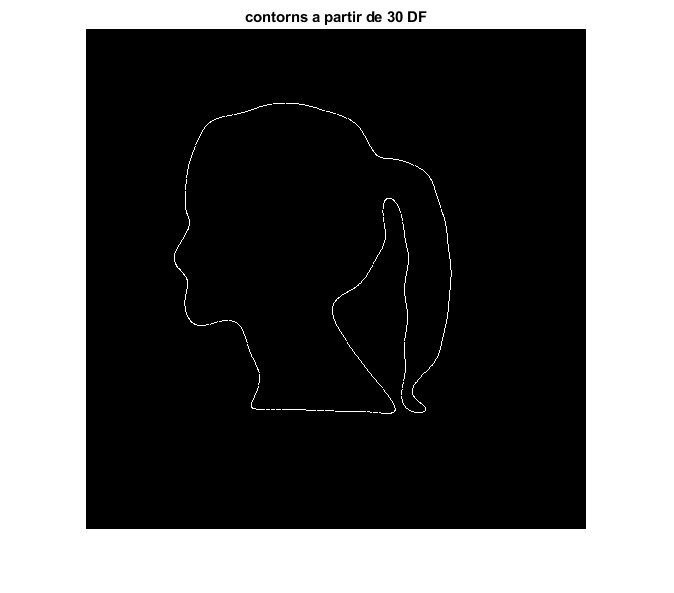

s2 = ifft(tmp);
aux = zeros(500);
files = round(real(s2)+250);
cols = round(imag(s2)+250);
aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux), title('contorns a partir de 30 DF')

## Exercici

#### Menys components

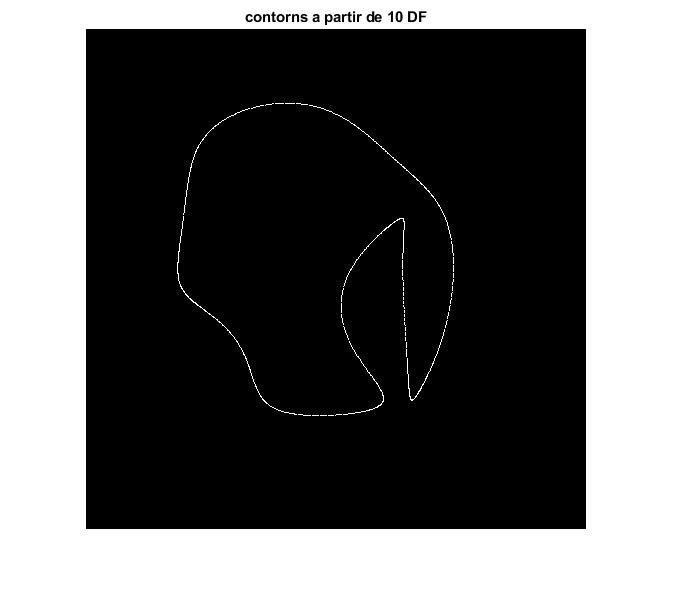

N = 8;
tmp = z;
tmp(N+1:end-N) = 0;
s2 = ifft(tmp);
aux = zeros(500);
files = round(real(s2)+250);
cols = round(imag(s2)+250);
aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux), title('contorns a partir de 10 DF')

#### Més components

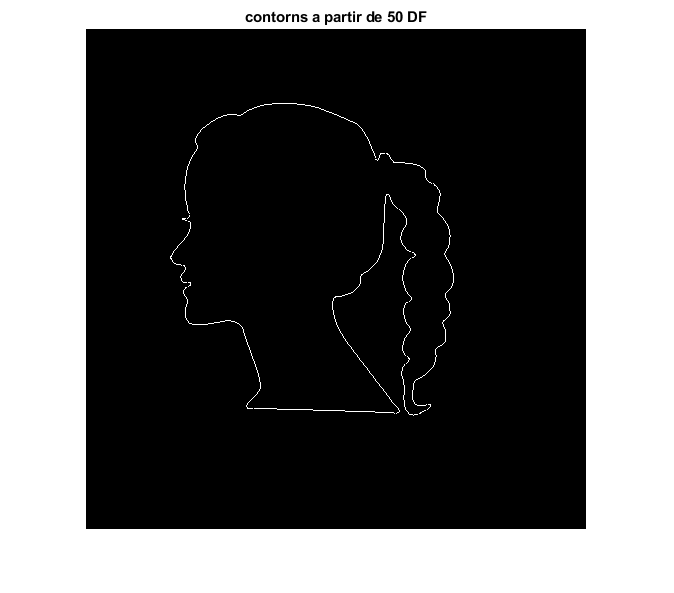

N = 150;
tmp = z;
tmp(N+1:end-N) = 0;
s2 = ifft(tmp);
aux = zeros(500);
files = round(real(s2)+250);
cols = round(imag(s2)+250);
aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux), title('contorns a partir de 50 DF')